clear variables
load('Tests/e1_coupled_tline/coupled_tl_28par_10std.mat')
[~,d] = size(training_samples);


training_samples = training_samples(1:870,:);
vouts_train = vouts_train(1:870,:);
m = 2;

tic
vouts_total2 = pc_collocation_total(training_samples,vouts_train,samples,m ,'Hermite');
norm(vouts_total2-vouts,"fro")/norm(vouts,"fro")

ans = 0.0299

toc

Elapsed time is 1.630149 seconds.


training_samples = training_samples2(1:8990,:);
vouts_train = vouts_train2(1:8990,:);
m = 3;

tic
vouts_total3 = pc_collocation_total(training_samples,vouts_train,samples,m ,'Hermite');
norm(vouts_total3-vouts,"fro")/norm(vouts,"fro")

ans = 0.0130

toc

Elapsed time is 34.714221 seconds.


training_samples = training_samples(1:660,:);
vouts_train = vouts_train(1:660,:);
m = 3;

N = (m+1)*ones(d,1);
r = 3;
x = TTrand(N,r);
x{1}(1,:) = [1 zeros(1,r-1)];
for i = 1:d-1
    x{i}(1:r,:)=eye(r);
end
x{d}(1:r) = [vouts_train(1,1); zeros(r-1,1)];

tic
 [vouts_Newton,PC_coefficients_TT,training_err,test_err,n_iterations] = ...
     pc_collocation_tensor_optimization(training_samples,vouts_train,x,samples,m,'Hermite','TT-Newton',0.3,0.2,r);

ans =     0.0075    0.0082    9.0000


ans =     0.0087    0.0089    1.0000


ans =     0.0097    0.0100    1.0000


ans =     0.0061    0.0075    2.0000


ans =     0.0081    0.0097    1.0000


ans =     0.0067    0.0093    2.0000


ans =     0.0062    0.0091    2.0000


ans =     0.0058    0.0079    2.0000


ans =     0.0055    0.0074    2.0000


ans =     0.0062    0.0071    2.0000


ans =     0.0059    0.0074    2.0000


ans =     0.0098    0.0097    1.0000


ans =     0.0064    0.0075    2.0000


ans =     0.0083    0.0096    1.0000


ans =     0.0056    0.0060    2.0000


ans =     0.0081    0.0092    1.0000


ans =     0.0057    0.0067    2.0000


ans =     0.0077    0.0081    1.0000


ans =     0.0055    0.0080    2.0000


ans =     0.0049    0.0064    2.0000


ans =     0.0053    0.0063    2.0000


ans =     0.0062    0.0071    2.0000


ans =     0.0069    0.0077    2.0000


ans =     0.0072    0.0090    2.0000


ans =     0.0066    0.0075    2.0000


ans =     0.0058    0.0071    2.0000


ans =     0.0086    0.0096    1.0000


ans =     0.0060    0.0070    2.0000


ans =     0.0056    0.0065    2.0000


ans =     0.0062    0.0074    2.0000


ans =     0.0070    0.0091    2.0000


ans =     0.0075    0.0091    2.0000


ans =     0.0072    0.0085    2.0000


ans =     0.0072    0.0074    2.0000


ans =     0.0070    0.0077    2.0000


ans =     0.0076    0.0080    2.0000


ans =     0.0078    0.0078    2.0000


ans =     0.0083    0.0081    2.0000


ans =     0.0075    0.0082    2.0000


ans =     0.0076    0.0087    2.0000


ans =     0.0068    0.0070    3.0000


ans =     0.0077    0.0080    2.0000


ans =     0.0096    0.0094    2.0000


ans =     0.0087    0.0092    3.0000


ans =     0.0073    0.0097    3.0000


ans =     0.0075    0.0097    2.0000


ans =     0.0068    0.0083    3.0000


ans =     0.0080    0.0099    2.0000


ans =     0.0076    0.0093    3.0000


ans =     0.0078    0.0095    3.0000


ans = 1×3
    0.0076    0.0096    2.0000


ans = 1×3
    0.0078    0.0093    2.0000


ans = 1×3
    0.0083    0.0095    2.0000


ans = 1×3
    0.0078    0.0091    3.0000


ans = 1×3
    0.0084    0.0098    2.0000


ans = 1×3
    0.0085    0.0097    2.0000


ans = 1×3
    0.0088    0.0100    2.0000


ans = 1×3
    0.0078    0.0086    3.0000


ans = 1×3
    0.0082    0.0098    3.0000


ans = 1×3
    0.0057    0.0108   17.0000


ans = 1×3
    0.0067    0.0123   11.0000


ans = 1×3
    0.0074    0.0099    3.0000


ans = 1×3
    0.0082    0.0100    2.0000


ans = 1×3
    0.0077    0.0092    3.0000


ans = 1×3
    0.0071    0.0090    4.0000


ans = 1×3
    0.0064    0.0115   12.0000


ans = 1×3
    0.0073    0.0143   11.0000


ans = 1×3
    0.0052    0.0108   20.0000


ans = 1×3
    0.0042    0.0101   12.0000


ans = 1×3
    0.0046    0.0100    4.0000


ans = 1×3
    0.0051    0.0088    4.0000


ans = 1×3
    0.0054    0.0094    4.0000


ans = 1×3
    0.0049    0.0099    5.0000


ans = 1×3
    0.0037    0.0100   11.0000


ans = 1×3
    0.0040    0.0118   10.0000


ans = 1×3
    0.0044    0.0142   12.0000


ans = 1×3
    0.0052    0.0172   10.0000


ans = 1×3
    0.0063    0.0211   11.0000


ans = 1×3
    0.0074    0.0240   12.0000


ans = 1×3
    0.0081    0.0234   12.0000


ans = 1×3
    0.0071    0.0202   12.0000


ans = 1×3
    0.0052    0.0136   12.0000


ans = 1×3
    0.0038    0.0101   12.0000


ans = 1×3
    0.0037    0.0137   11.0000


ans = 1×3
    0.0047    0.0190   10.0000


ans = 1×3
    0.0064    0.0208   11.0000


ans = 1×3
    0.0072    0.0208   11.0000


ans = 1×3
    0.0062    0.0184   12.0000


ans = 1×3
    0.0066    0.0204   11.0000


ans = 1×3
    0.0080    0.0225   15.0000


ans = 1×3
    0.0077    0.0172   12.0000


ans = 1×3
    0.0059    0.0130   12.0000


ans = 1×3
    0.0046    0.0113   12.0000


ans = 1×3
    0.0044    0.0124   10.0000


ans = 1×3
    0.0050    0.0175   11.0000


ans = 1×3
    0.0079    0.0337    4.0000


ans = 1×3
    0.0142    0.0588    3.0000


ans = 1×3
    0.0175    0.0777    6.0000


ans = 1×3
    0.0167    0.0559   18.0000


ans = 1×3
    0.0136    0.0343   13.0000


norm(vouts_Newton-vouts,"fro")/norm(vouts,"fro")

ans = 0.0131

toc

Elapsed time is 39.085660 seconds.


training_samples = training_samples(1:660,:);
vouts_train = vouts_train(1:660,:);
m = 3;

N = (m+1)*ones(d,1);
r = 3;
x = TTrand(N,r);
x{1}(1,:) = [1 zeros(1,r-1)];
for i = 1:d-1
    x{i}(1:r,:)=eye(r);
end
x{d}(1:r) = [vouts_train(1,1); zeros(r-1,1)];

tic
 [vouts_ALS,PC_coefficients_ALS,training_err,test_err,n_iterations] = ...
     pc_collocation_tensor_optimization(training_samples,vouts_train,x,samples,m,'Hermite','TT-ALS',0.3,0.2,r);

ans =     0.0069    0.0141  169.0000


ans =     0.0042    0.0098   80.0000


ans =     0.0051    0.0097   27.0000


ans =     0.0042    0.0097   43.0000


ans =     0.0041    0.0099   49.0000


ans =     0.0043    0.0099   51.0000


ans =     0.0043    0.0098   54.0000


ans =     0.0048    0.0099   46.0000


ans =     0.0056    0.0100   26.0000


ans =     0.0052    0.0096   47.0000


ans =     0.0047    0.0095   78.0000


ans =     0.0049    0.0098   51.0000


ans =     0.0050    0.0097   53.0000


ans =     0.0042    0.0100   72.0000


ans =     0.0035    0.0100   79.0000


ans =     0.0042    0.0099   49.0000


ans =     0.0044    0.0093   49.0000


ans =     0.0044    0.0097   47.0000


ans =     0.0043    0.0097   47.0000


ans =     0.0044    0.0100   47.0000


ans =     0.0052    0.0096   49.0000


ans =     0.0041    0.0099   99.0000


ans =     0.0038    0.0100  127.0000


ans =     0.0035    0.0098  134.0000


ans =     0.0034    0.0099   99.0000


ans =     0.0044    0.0098   51.0000


ans =     0.0042    0.0099   75.0000


ans =     0.0045    0.0100   61.0000


ans =     0.0047    0.0100   62.0000


ans =     0.0044    0.0099   78.0000


ans =     0.0032    0.0101  142.0000


ans =     0.0039    0.0099  100.0000


ans =     0.0052    0.0098   54.0000


ans =     0.0054    0.0100   54.0000


ans =     0.0059    0.0099   52.0000


ans =     0.0061    0.0100   52.0000


ans =     0.0048    0.0100   88.0000


ans =     0.0046    0.0098  101.0000


ans =     0.0047    0.0098  103.0000


ans =     0.0048    0.0097  103.0000


ans =     0.0051    0.0100  107.0000


ans =     0.0048    0.0109  142.0000


ans =     0.0048    0.0126  168.0000


ans =     0.0047    0.0131  170.0000


ans =     0.0041    0.0104  170.0000


ans =     0.0045    0.0100  109.0000


ans =     0.0051    0.0112  116.0000


ans =     0.0050    0.0131  168.0000


ans =     0.0056    0.0156  169.0000


ans =     0.0052    0.0147  169.0000


ans = 1×3
    0.0049    0.0137  115.0000


ans = 1×3
    0.0044    0.0112  115.0000


ans = 1×3
    0.0049    0.0122  115.0000


ans = 1×3
    0.0056    0.0144  115.0000


ans = 1×3
    0.0044    0.0123  169.0000


ans = 1×3
    0.0053    0.0138  115.0000


ans = 1×3
    0.0048    0.0126  168.0000


ans = 1×3
    0.0049    0.0129  196.0000


ans = 1×3
    0.0055    0.0149  222.0000


ans = 1×3
    0.0068    0.0196  223.0000


ans = 1×3
    0.0064    0.0163  276.0000


ans = 1×3
    0.0058    0.0126  221.0000


ans = 1×3
    0.0042    0.0100  217.0000


ans = 1×3
    0.0040    0.0106  168.0000


ans = 1×3
    0.0040    0.0106  168.0000


ans = 1×3
    0.0041    0.0115  168.0000


ans = 1×3
    0.0050    0.0171  170.0000


ans = 1×3
    0.0060    0.0198  167.0000


ans = 1×3
    0.0061    0.0187  166.0000


ans = 1×3
    0.0053    0.0161  168.0000


ans = 1×3
    0.0047    0.0138  196.0000


ans = 1×3
    0.0044    0.0118  201.0000


ans = 1×3
    0.0041    0.0111  218.0000


ans = 1×3
    0.0050    0.0125  142.0000


ans = 1×3
    0.0055    0.0132  142.0000


ans = 1×3
    0.0050    0.0148  196.0000


ans = 1×3
    0.0059    0.0186  142.0000


ans = 1×3
    0.0072    0.0204  143.0000


ans = 1×3
    0.0076    0.0213  196.0000


ans = 1×3
    0.0083    0.0227  220.0000


ans = 1×3
    0.0090    0.0218  168.0000


ans = 1×3
    0.0069    0.0174  222.0000


ans = 1×3
    0.0063    0.0184  168.0000


ans = 1×3
    0.0071    0.0285  130.0000


ans = 1×3
    0.0128    0.0516   75.0000


ans = 1×3
    0.0137    0.0548  130.0000


ans = 1×3
    0.0109    0.0359  220.0000


ans = 1×3
    0.0095    0.0326  169.0000


ans = 1×3
    0.0083    0.0279  205.0000


ans = 1×3
    0.0095    0.0282  200.0000


ans = 1×3
    0.0087    0.0237  223.0000


ans = 1×3
    0.0074    0.0176  169.0000


ans = 1×3
    0.0063    0.0140  169.0000


ans = 1×3
    0.0056    0.0144  219.0000


ans = 1×3
    0.0065    0.0195  220.0000


ans = 1×3
    0.0108    0.0432  123.0000


ans = 1×3
    0.0196    0.0783   78.0000


ans = 1×3
    0.0214    0.0859  132.0000


ans = 1×3
    0.0185    0.0676  261.0000


ans = 1×3
    0.0146    0.0400  220.0000


norm(vouts_ALS-vouts,"fro")/norm(vouts,"fro")

ans = 0.0173

toc

Elapsed time is 79.046136 seconds.


training_samples = training_samples(1:660,:);
vouts_train = vouts_train(1:660,:);
m = 3;
r = 8;
x = cell(d,1);
for i = 1:d
    x{i} = zeros(m+1,1);
end


tic
 [vouts_GD,PC_coefficients_GD,training_err,test_err,n_iterations] = ...
     pc_collocation_tensor_optimization(training_samples,vouts_train,x,samples,m,'Hermite','TT-SGD',0.3,0.2,r,60,15);

ans =     0.0007    0.0097   54.0000


ans =     0.0007    0.0098   49.0000


ans =     0.0007    0.0097   51.0000


ans =     0.0009    0.0095   52.0000


ans =     0.0009    0.0095   59.0000


ans =     0.0008    0.0096   52.0000


ans =     0.0007    0.0097   61.0000


ans =     0.0009    0.0100   41.0000


ans =     0.0007    0.0093   66.0000


ans =     0.0007    0.0099   47.0000


ans =     0.0008    0.0098   55.0000


ans =     0.0009    0.0098   36.0000


ans =     0.0007    0.0098   75.0000


ans =     0.0008    0.0100   60.0000


ans =     0.0008    0.0098   49.0000


ans =     0.0009    0.0099   60.0000


ans =     0.0007    0.0099   61.0000


ans =     0.0008    0.0095   49.0000


ans =     0.0009    0.0100   58.0000


ans =     0.0007    0.0098   58.0000


ans =     0.0007    0.0098   86.0000


ans =     0.0007    0.0100   76.0000


ans =     0.0007    0.0100  106.0000


ans =     0.0007    0.0100   90.0000


ans =     0.0006    0.0100   96.0000


ans =     0.0008    0.0099   76.0000


ans =     0.0007    0.0100   95.0000


ans =     0.0008    0.0100   84.0000


ans =     0.0007    0.0099   81.0000


ans =     0.0006    0.0098  134.0000


ans =     0.0005    0.0100  140.0000


ans =     0.0007    0.0100   99.0000


ans =     0.0010    0.0099   53.0000


ans =     0.0007    0.0099  107.0000


ans =     0.0005    0.0106  150.0000


ans =     0.0007    0.0107  150.0000


ans =     0.0008    0.0122  150.0000


ans =     0.0007    0.0139  150.0000


ans =     0.0007    0.0126  150.0000


ans =     0.0006    0.0114  150.0000


ans =     0.0007    0.0100  147.0000


ans =     0.0007    0.0103  150.0000


ans =     0.0009    0.0141  150.0000


ans =     0.0009    0.0130  150.0000


ans =     0.0007    0.0121  150.0000


ans =     0.0008    0.0132  150.0000


ans =     0.0007    0.0193  150.0000


ans =     0.0011    0.0240  150.0000


ans =     0.0013    0.0238  150.0000


ans =     0.0013    0.0206  150.0000


ans = 1×3
    0.0011    0.0179  150.0000


ans = 1×3
    0.0013    0.0202  150.0000


ans = 1×3
    0.0012    0.0188  150.0000


ans = 1×3
    0.0012    0.0186  150.0000


ans = 1×3
    0.0010    0.0148  150.0000


ans = 1×3
    0.0008    0.0123  150.0000


ans = 1×3
    0.0007    0.0115  150.0000


ans = 1×3
    0.0009    0.0156  150.0000


ans = 1×3
    0.0012    0.0270   93.0000


ans = 1×3
    0.0013    0.0345  150.0000


ans = 1×3
    0.0019    0.0378  150.0000


ans = 1×3
    0.0020    0.0349  150.0000


ans = 1×3
    0.0021    0.0281  139.0000


ans = 1×3
    0.0017    0.0285  150.0000


ans = 1×3
    0.0015    0.0229  150.0000


ans = 1×3
    0.0013    0.0245  150.0000


ans = 1×3
    0.0015    0.0350  150.0000


ans = 1×3
    0.0019    0.0413  150.0000


ans = 1×3
    0.0022    0.0406  150.0000


ans = 1×3
    0.0019    0.0358  150.0000


ans = 1×3
    0.0022    0.0399  150.0000


ans = 1×3
    0.0027    0.0325  150.0000


ans = 1×3
    0.0026    0.0330  139.0000


ans = 1×3
    0.0025    0.0404  150.0000


ans = 1×3
    0.0025    0.0475  150.0000


ans = 1×3
    0.0029    0.0542  127.0000


ans = 1×3
    0.0028    0.0538  150.0000


ans = 1×3
    0.0025    0.0541  150.0000


ans = 1×3
    0.0026    0.0517  132.0000


ans = 1×3
    0.0026    0.0478  150.0000


ans = 1×3
    0.0027    0.0408  150.0000


ans = 1×3
    0.0027    0.0338  150.0000


ans = 1×3
    0.0020    0.0341  150.0000


ans = 1×3
    0.0020    0.0482  132.0000


ans = 1×3
    0.0024    0.0682  150.0000


ans = 1×3
    0.0035    0.0877  150.0000


ans = 1×3
    0.0048    0.0913  144.0000


ans = 1×3
    0.0048    0.0684  150.0000


ans = 1×3
    0.0037    0.0714  150.0000


ans = 1×3
    0.0047    0.0703  150.0000


ans = 1×3
    0.0042    0.0525  150.0000


ans = 1×3
    0.0029    0.0390  150.0000


ans = 1×3
    0.0025    0.0411  141.0000


ans = 1×3
    0.0023    0.0411  150.0000


ans = 1×3
    0.0025    0.0521  150.0000


ans = 1×3
    0.0026    0.0806  150.0000


ans = 1×3
    0.0037    0.1083  150.0000


ans = 1×3
    0.0057    0.1186  150.0000


ans = 1×3
    0.0088    0.1193  150.0000


ans = 1×3
    0.0109    0.1388  121.0000


norm(vouts_GD-vouts,"fro")/norm(vouts,"fro")

ans = 0.0323

toc

Elapsed time is 203.107378 seconds.


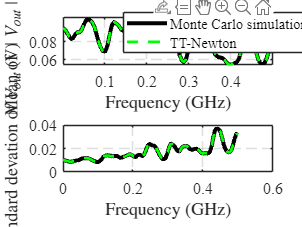

vout_mean0 = mean(abs(vouts));
vout_sigma0 = std((vouts));

vout_mean1 = mean(abs(vouts_Newton));
vout_sigma1 = std((vouts_Newton));


fpoints = linspace(0,5e8,100);
scale = 1e9;
f = figure(2);
subplot(2,1,1);
hold on
plot(fpoints/scale,vout_mean0,'k-','LineWidth',3);
plot(fpoints/scale,vout_mean1,'g--','LineWidth',2);
legend('Monte Carlo simulation','TT-Newton')
grid on
xlabel('Frequency (GHz)','interpreter','LaTex')
ylabel('Mean of $ \mid V_{out} \mid $ (V)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;


subplot(2,1,2);
hold on
plot(fpoints/scale,vout_sigma0,'k-','LineWidth',3);
plot(fpoints/scale,vout_sigma1,'g--','LineWidth',2);
ylim([0.0 0.04])
grid on
ylabel('Standard devation of $ V_{out} $ (V)','interpreter','LaTex')
xlabel('Frequency (GHz)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;


f.Position = [100 100 675 500];

pdf_freq_idx = 100;
figure(1)
histogram(abs(vouts(:,pdf_freq_idx)),50,'Normalization','pdf', 'DisplayStyle','bar', 'FaceColor',[0.7 0.7 0.7]);
hold on
grid on
[N,edges] = histcounts(abs(vouts_Newton(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'b--','LineWidth',3)
[N,edges] = histcounts(abs(vouts_total2(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'r--','LineWidth',2)
[N,edges] = histcounts(abs(vouts_total3(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'c--','LineWidth',2)
% [N,edges] = histcounts(abs(vouts_GD(:,pdf_freq_idx)), 'Normalization', 'pdf');
% plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'--','LineWidth',2)
% [N,edges] = histcounts(abs(vouts_ALS(:,pdf_freq_idx)), 'Normalization', 'pdf');
% plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'--','LineWidth',2)
xlim([0.02 0.12])
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
legend('MC', 'TT-Newton','Total order(m=2)','Total order(m=3)','interpreter','LaTex');